# `Μαθηματικά ΙΙ`

## **Εξαμηνιαία εργασία 2 **

# [Βέργος] [Γεώργιος], 1072604. 

## Ερώτημα 1.1

%gia tin epilusi tou parontos erotimatos  opws kai twn upoloipwn xrisimopoiiste to paron code box
%gia gracete ta programmata sas
syms x y LocMin LocMax Saddle Unknown
f_0(x,y)=6-x^2-4*y^2

$$f\_0(x, y) = -x^{2}-4\,y^{2}+6$$

grad_f_0=gradient(f_0,[x y])

$$grad\_f\_0(x, y) = \left(\begin{array}{c} -2\,x\\ -8\,y \end{array}\right)$$

hess=hessian(f_0,[x y]);H=hess(x,y)

$$H = \left(\begin{array}{cc} -2 & 0\\ 0 & -8 \end{array}\right)$$

LPMD(x,y)=[H(1,1),det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} -2 & 16 \end{array}\right)$$

c=solve(grad_f_0==[0 0],[x y])

c = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


M=[c.x c.y],m=size(M,1)

$$M = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

m = 1

disp('x y LPMD Type')

x y LPMD Type


for k=1:m
    xp=M(k,1); yp=M(k,2); P=[xp yp]; L=LPMD(xp,yp);
    if L(1)>0 && L(2)>0
        T=LocMin;
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    elseif L(2)<0
        T=Saddle;
    else
        T=Unknown;
    end
    r=[P f_0(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} 0 & 0 & 6 & -2 & 16 & \mathrm{LocMax} \end{array}\right)$$

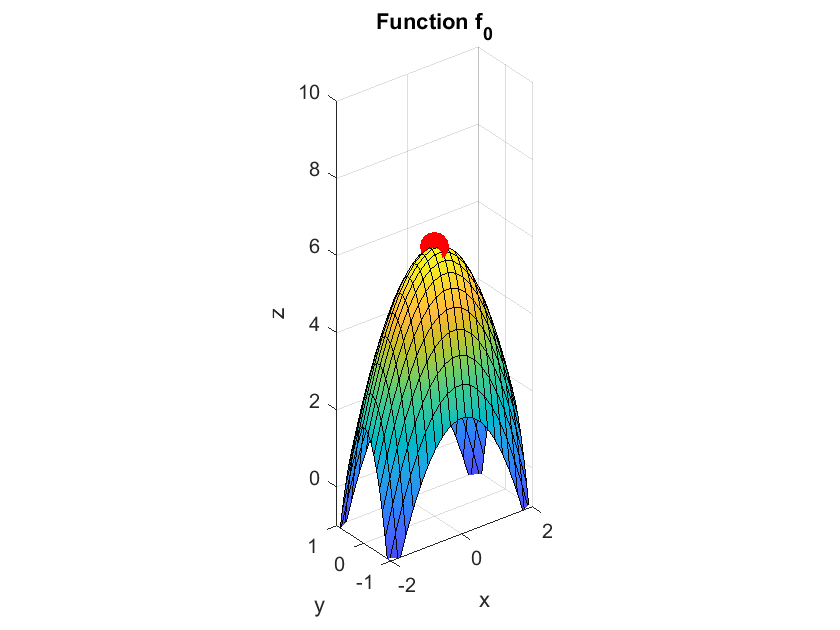

figure
fsurf(f_0(x,y),[-2 2 -1 1],'MeshDensity',20); hold on
plot3(c.x,c.y,f_0(c.x,c.y),'ro','MarkerFaceColor','r','MarkerSize',14)
axis equal; axis([-2 2 -1 1 -1 10])
xlabel('x'); ylabel('y'); zlabel('z')
title('Function f_0')

%Function f_1
f_1(x,y)=x*y*exp(-x -y)

$$f\_1(x, y) = x\,y\,{\mathrm{e}}^{-x-y}$$

grad_f_1=gradient(f_1,[x y])

$$grad\_f\_1(x, y) = \left(\begin{array}{c} y\,{\mathrm{e}}^{-x-y}-x\,y\,{\mathrm{e}}^{-x-y}\\ x\,{\mathrm{e}}^{-x-y}-x\,y\,{\mathrm{e}}^{-x-y} \end{array}\right)$$

hess=hessian(f_1,[x y]);H=hess(x,y)

$$H = \begin{array}{l} \left(\begin{array}{cc} x\,y\,{\mathrm{e}}^{-x-y}-2\,y\,{\mathrm{e}}^{-x-y} & \sigma_{1}\\ \sigma_{1} & x\,y\,{\mathrm{e}}^{-x-y}-2\,x\,{\mathrm{e}}^{-x-y} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x-y}-x\,{\mathrm{e}}^{-x-y}-y\,{\mathrm{e}}^{-x-y}+x\,y\,{\mathrm{e}}^{-x-y} \end{array}$$

LPMD(x,y)=[H(1,1),det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} x\,y\,{\mathrm{e}}^{-x-y}-2\,y\,{\mathrm{e}}^{-x-y} & -{\mathrm{e}}^{-2\,x-2\,y}\,\left(x^{2}-2\,x+y^{2}-2\,y+1\right) \end{array}\right)$$

c=solve(grad_f_1==[0 0],[x y])

c = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


M=[c.x c.y],m=size(M,1)

$$M = \left(\begin{array}{cc} 0 & 0\\ 1 & 1 \end{array}\right)$$

m = 2

disp('x y LPMD Type')

x y LPMD Type


for k=1:m
    xp=M(k,1); yp=M(k,2); P=[xp yp]; L=LPMD(xp,yp);
    if L(1)>0 && L(2)>0
        T=LocMin;
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    elseif L(2)<0
        T=Saddle;
    else
        T=Unknown;
    end
    r=[P f_1(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & -1 & \mathrm{Saddle} \end{array}\right)$$

$$\left(\begin{array}{cccccc} 1 & 1 & {\mathrm{e}}^{-2} & -{\mathrm{e}}^{-2} & {\mathrm{e}}^{-4} & \mathrm{LocMax} \end{array}\right)$$

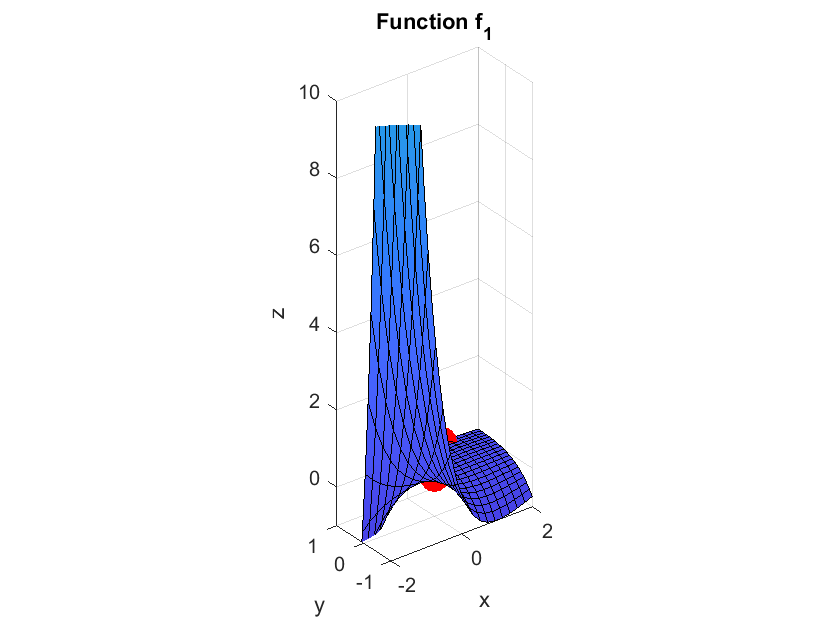

figure
fsurf(f_1(x,y),[-2 2 -1 1],'MeshDensity',20); hold on
plot3(c.x,c.y,f_1(c.x,c.y),'ro','MarkerFaceColor','r','MarkerSize',14)
axis equal; axis([-2 2 -1 1 -1 10])
xlabel('x'); ylabel('y'); zlabel('z')
title('Function f_1')

%Function f2
f_2(x,y)=(4*x-1)^2+(2*y+4)^2+1

$$f\_2(x, y) = {\left(4\,x-1\right)}^{2}+{\left(2\,y+4\right)}^{2}+1$$

grad_f_2=gradient(f_2,[x y])

$$grad\_f\_2(x, y) = \left(\begin{array}{c} 32\,x-8\\ 8\,y+16 \end{array}\right)$$

hess=hessian(f_2,[x y]);H=hess(x,y)

$$H = \left(\begin{array}{cc} 32 & 0\\ 0 & 8 \end{array}\right)$$

LPMD(x,y)=[H(1,1),det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} 32 & 256 \end{array}\right)$$

c=solve(grad_f_2==[0 0],[x y])

c = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


M=[c.x c.y],m=size(M,1)

$$M = \left(\begin{array}{cc} \frac{1}{4} & -2 \end{array}\right)$$

m = 1

disp('x y LPMD Type')

x y LPMD Type


for k=1:m
    xp=M(k,1); yp=M(k,2); P=[xp yp]; L=LPMD(xp,yp);
    if L(1)>0 && L(2)>0
        T=LocMin;
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    elseif L(2)<0
        T=Saddle;
    else
        T=Unknown;
    end
    r=[P f_2(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} \frac{1}{4} & -2 & 1 & 32 & 256 & \mathrm{LocMin} \end{array}\right)$$

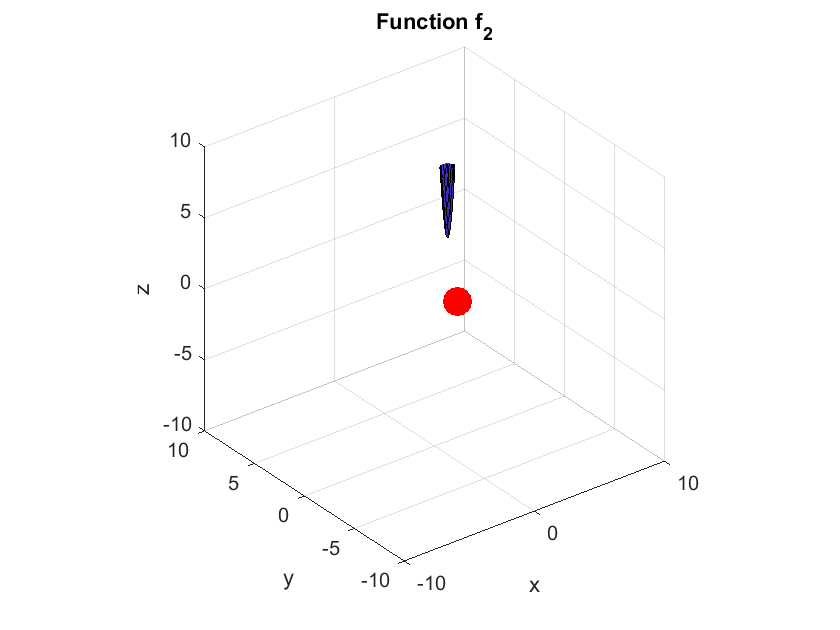

figure
fsurf(f_2(x,y),[-2 2 -1 1],'MeshDensity',20); hold on
plot3(c.x,c.y,f_2(c.x,c.y),'ro','MarkerFaceColor','r','MarkerSize',14)
axis equal; axis([-10 10 -10 10 -10 10])
xlabel('x'); ylabel('y'); zlabel('z')
title('Function f_2')

%function f_4
f_4(x,y)=atan(x*y)

$$f\_4(x, y) = \mathrm{atan}\left(x\,y\right)$$

grad_f_4=gradient(f_4,[x y])

$$grad\_f\_4(x, y) = \left(\begin{array}{c} \frac{y}{x^{2}\,y^{2}+1}\\ \frac{x}{x^{2}\,y^{2}+1} \end{array}\right)$$

hess=hessian(f_4,[x y]);H=hess(x,y)

$$H = \begin{array}{l} \left(\begin{array}{cc} -\frac{2\,x\,y^{3}}{\sigma_{2}} & \sigma_{1}\\ \sigma_{1} & -\frac{2\,x^{3}\,y}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{x^{2}\,y^{2}+1}-\frac{2\,x^{2}\,y^{2}}{\sigma_{2}}\\ \sigma_{2}={\left(x^{2}\,y^{2}+1\right)}^{2} \end{array}$$

LPMD(x,y)=[H(1,1),det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} -\frac{2\,x\,y^{3}}{{\left(x^{2}\,y^{2}+1\right)}^{2}} & \frac{3\,x^{2}\,y^{2}-1}{{\left(x^{2}\,y^{2}+1\right)}^{3}} \end{array}\right)$$

c=solve(grad_f_4==[0 0],[x y])

c = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


M=[c.x c.y],m=size(M,1)

$$M = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

m = 1

disp('x y LPMD Type')

x y LPMD Type


for k=1:m
    xp=M(k,1); yp=M(k,2); P=[xp yp]; L=LPMD(xp,yp);
    if L(1)>0 && L(2)>0
        T=LocMin;
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    elseif L(2)<0
        T=Saddle;
    else
        T=Unknown;
    end
    r=[P f_4(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & -1 & \mathrm{Saddle} \end{array}\right)$$

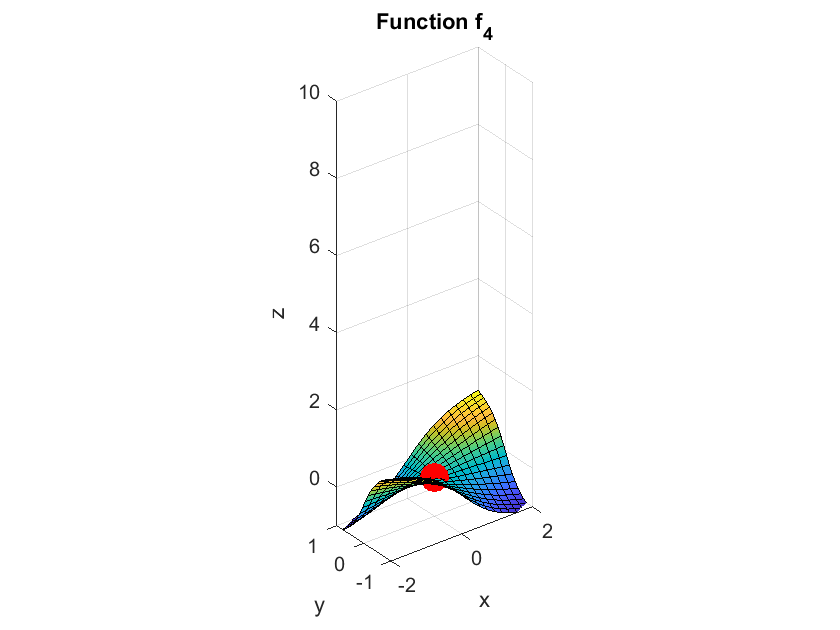

figure
fsurf(f_4(x,y),[-2 2 -1 1],'MeshDensity',20); hold on
plot3(c.x,c.y,f_4(c.x,c.y),'ro','MarkerFaceColor','r','MarkerSize',14)
axis equal; axis([-2 2 -1 1 -1 10])
xlabel('x'); ylabel('y'); zlabel('z')
title('Function f_4')

%function f_6
f_6(x,y)=x^2+x*y^2-2*x+1

$$f\_6(x, y) = x^{2}+x\,y^{2}-2\,x+1$$

grad_f_6=gradient(f_0,[x y])

$$grad\_f\_6(x, y) = \left(\begin{array}{c} -2\,x\\ -8\,y \end{array}\right)$$

hess=hessian(f_6,[x y]);H=hess(x,y)

$$H = \left(\begin{array}{cc} 2 & 2\,y\\ 2\,y & 2\,x \end{array}\right)$$

LPMD(x,y)=[H(1,1),det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} 2 & 4\,x-4\,y^{2} \end{array}\right)$$

c=solve(grad_f_6==[0 0],[x y])

c = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


M=[c.x c.y],m=size(M,1)

$$M = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

m = 1

disp('x y LPMD Type')

x y LPMD Type


for k=1:m
    xp=M(k,1); yp=M(k,2); P=[xp yp]; L=LPMD(xp,yp);
    if L(1)>0 && L(2)>0
        T=LocMin;
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    elseif L(2)<0
        T=Saddle;
    else
        T=Unknown;
    end
    r=[P f_6(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} 0 & 0 & 1 & 2 & 0 & \mathrm{Unknown} \end{array}\right)$$

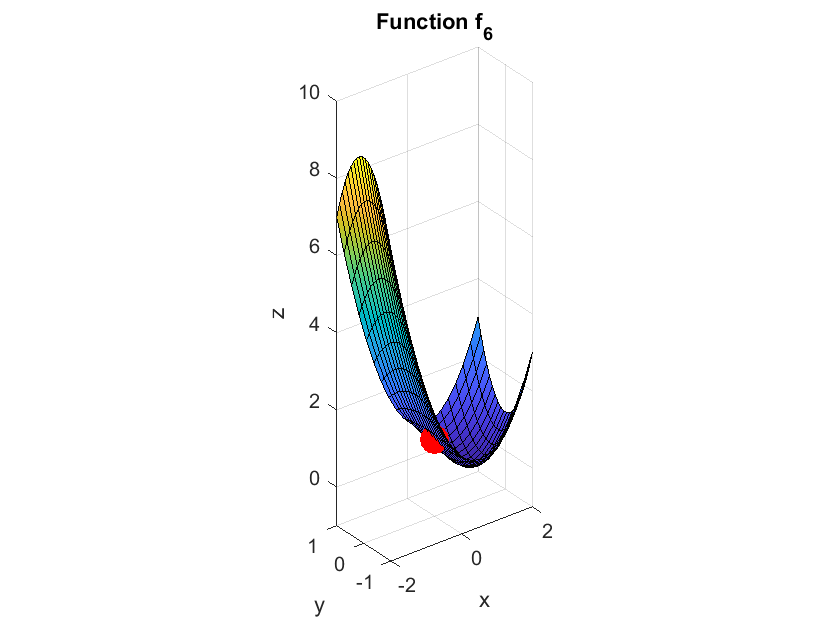

figure
fsurf(f_6(x,y),[-2 2 -1 1],'MeshDensity',20); hold on
plot3(c.x,c.y,f_6(c.x,c.y),'ro','MarkerFaceColor','r','MarkerSize',14)
axis equal; axis([-2 2 -1 1 -1 10])
xlabel('x'); ylabel('y'); zlabel('z')
title('Function f_6')

%function f_7
f_7(x,y)=x/(x^2+y^2+1)

$$f\_7(x, y) = \frac{x}{x^{2}+y^{2}+1}$$

grad_f_7=gradient(f_7,[x y])

$$grad\_f\_7(x, y) = \left(\begin{array}{c} \frac{1}{x^{2}+y^{2}+1}-\frac{2\,x^{2}}{{\left(x^{2}+y^{2}+1\right)}^{2}}\\ -\frac{2\,x\,y}{{\left(x^{2}+y^{2}+1\right)}^{2}} \end{array}\right)$$

hess=hessian(f_7,[x y]);H=hess(x,y)

$$H = \begin{array}{l} \left(\begin{array}{cc} \frac{8\,x^{3}}{{\left(x^{2}+y^{2}+1\right)}^{3}}-\frac{6\,x}{{\left(x^{2}+y^{2}+1\right)}^{2}} & \sigma_{1}\\ \sigma_{1} & \frac{8\,x\,y^{2}}{{\left(x^{2}+y^{2}+1\right)}^{3}}-\frac{2\,x}{{\left(x^{2}+y^{2}+1\right)}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{8\,x^{2}\,y}{{\left(x^{2}+y^{2}+1\right)}^{3}}-\frac{2\,y}{{\left(x^{2}+y^{2}+1\right)}^{2}} \end{array}$$

LPMD(x,y)=[H(1,1),det(H)]

$$LPMD(x, y) = \left(\begin{array}{cc} \frac{8\,x^{3}}{{\left(x^{2}+y^{2}+1\right)}^{3}}-\frac{6\,x}{{\left(x^{2}+y^{2}+1\right)}^{2}} & -\frac{4\,\left(x^{4}+2\,x^{2}\,y^{2}-3\,x^{2}+y^{4}+y^{2}\right)}{{\left(x^{2}+y^{2}+1\right)}^{5}} \end{array}\right)$$

c=solve(grad_f_7==[0 0],[x y])

c = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


M=[c.x c.y],m=size(M,1)

$$M = \left(\begin{array}{cc} -1 & 0\\ 1 & 0 \end{array}\right)$$

m = 2

disp('x y LPMD Type')

x y LPMD Type


for k=1:m
    xp=M(k,1); yp=M(k,2); P=[xp yp]; L=LPMD(xp,yp);
    if L(1)>0 && L(2)>0
        T=LocMin;
    elseif L(1)<0 && L(2)>0
        T=LocMax;
    elseif L(2)<0
        T=Saddle;
    else
        T=Unknown;
    end
    r=[P f_7(xp,yp) L T];
    disp(r)
end

$$\left(\begin{array}{cccccc} -1 & 0 & -\frac{1}{2} & \frac{1}{2} & \frac{1}{4} & \mathrm{LocMin} \end{array}\right)$$

$$\left(\begin{array}{cccccc} 1 & 0 & \frac{1}{2} & -\frac{1}{2} & \frac{1}{4} & \mathrm{LocMax} \end{array}\right)$$

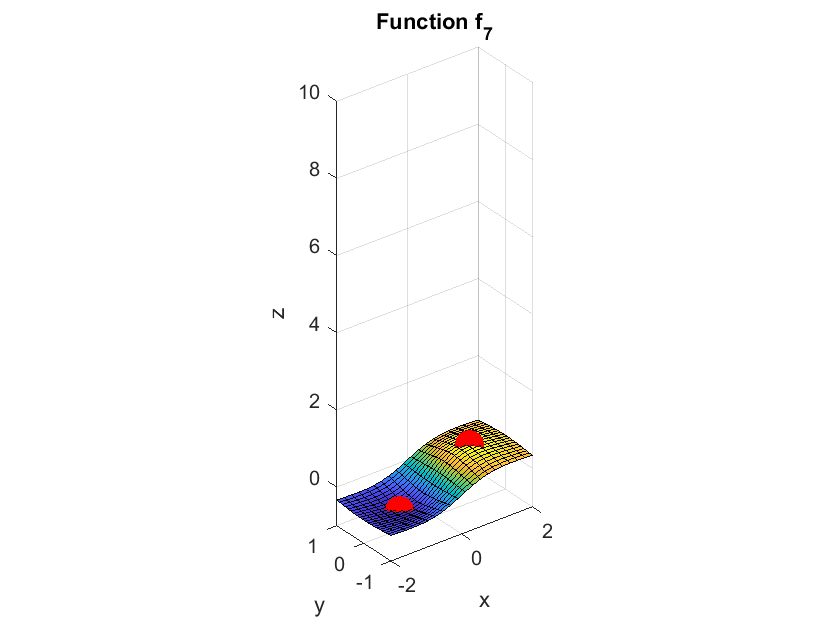

figure
fsurf(f_7(x,y),[-2 2 -1 1],'MeshDensity',20); hold on
plot3(c.x,c.y,f_7(c.x,c.y),'ro','MarkerFaceColor','r','MarkerSize',14)
axis equal; axis([-2 2 -1 1 -1 10])
xlabel('x'); ylabel('y'); zlabel('z')
title('Function f_7')


$$E\rho ώ\tau \eta \mu \alpha \:1.2\\\Gamma \iota \alpha \:\nu \alpha \:\varepsilon ί\nu \alpha \iota \:\sigma \upsilon \nu \varepsilon \chi ής\:\sigma \tau o\:(0,0)\:\theta \alpha \:\pi \rho έ\pi \varepsilon \iota $$



$$$$ \lim_{(x,y)\to(0,0)}f(x,y)=\lim_{x\to0}\lim_{y\to0}f(x,y)=\lim_{y\to0}\lim_{x\to0}f(x,y)$$ $$



$$\Omega \sigma \tau ό\sigma o:$$



$$$$\lim_{y\to0^-}f(x,y)=0\:\kappa \alpha \iota \:\lim_{y\to0^+}f(x,y)=1\:\delta \eta \lambda \alpha \delta ή:\\ \delta \varepsilon \nu \: \upsilon \pi ά\rho \chi \varepsilon \iota \:\tau o:\:\lim_{y\to0}f(x,y)  $$$$



$$Έ\tau \sigma \iota \:\tau o :$$



$$$$ \lim_{x\to0}\lim_{y\to0}f(x,y)\:\delta \varepsilon \nu \:\upsilon \varphi ί\sigma \tau \alpha \tau \alpha \iota \:o\pi ό\tau \varepsilon \:\pi \rho o\varphi \alpha \nu ώς\: \\ \delta \varepsilon \: 
\theta \alpha \:\mu \pi o\rho \varepsilon ί\:\nu \alpha \:\iota \sigma oύ\tau \alpha \iota \:\mu \varepsilon \:\tau o:\:\lim_{y\to0}\lim_{x\to0}f(x,y)\:(\alpha \nu \: \upsilon \pi ά\rho \chi \varepsilon \iota )\\ ά\rho \alpha \:\tau o\:\lim_{(x,y)\to(0,0)}f(x,y)\:\delta \varepsilon \nu \:\upsilon \pi ά\rho \chi \varepsilon \iota \:o\pi ό\tau \varepsilon \:\eta \: f\:\delta \varepsilon \nu \: \mu \pi o\rho \varepsilon ί\:\nu \alpha \:\varepsilon ί\nu \alpha \iota \:\sigma \upsilon \nu \varepsilon \chi ής\:\sigma \tau o\:(0,0) (\varepsilon \rho ώ\tau \eta \mu \alpha \:ii) $$$$



$$\Pi \alpha \rho \alpha \tau \eta \rho ώ \:ό\tau \iota  \:\alpha \pi ό \:\tau \eta  \:\gamma \rho \alpha \varphi \iota \kappa ή \:\pi \alpha \rho ά\sigma \tau \alpha \sigma \eta  \:\tau \eta ς \:\sigma \upsilon \nu ά\rho \tau \eta \sigma \eta ς\: \pi o\upsilon  \:o \:\pi \alpha \rho \alpha \kappa ά\tau \omega \:\\ \kappa ώ\delta \iota \kappa \alpha ς \:\sigma \varepsilon  \:matlab\: \upsilon \lambda o\pi oί\varepsilon \iota \: \sigma \upsilon \mu \pi \alpha \iota \rho \alpha ί\nu \omega  \:ό\tau \iota  \:\eta  \:f \:\delta \varepsilon \nu \: \varepsilon ί\nu \alpha \iota \\ \:\sigma \upsilon \nu \varepsilon \chi ής\: \sigma \tau o\: (0,0).\: E\pi \iota \pi \lambda έo\nu  \:\alpha \nu \tau \lambda ώ \:\tau \eta \nu \: \pi \lambda \eta \rho o\varphi o\rho ί\alpha \: ό\tau \iota \: ό\tau \alpha \nu \: \eta \: f(x,y)->0\: \tau ό\tau \varepsilon \: (x,y)->(0,0) \:\alpha \nu \varepsilon \xi ά\rho \tau ή\tau \omega ς\: \delta \iota \alpha \delta \rho o\mu ής\: \pi o\upsilon \: \\\pi \rho o\sigma \varepsilon \gamma \gamma ί\zeta \omega \: \tau o\: (0,0)\: \mu έ\sigma \omega \: \tau \eta ς\: \pi \alpha \rho \alpha \mu \varepsilon \tau \rho \iota \kappa ής\: \gamma \rho \alpha \mu \mu ής:\:$$



$$$$ y=mx^a ,0<a<4(\varepsilon \rho ώ\tau \eta \mu \alpha \:ii)$$$$



$$$$


syms x y 
f(x,y)=piecewise(y<=0|y>=x^4,0,0<y<x^4,1)

$$f(x, y) = \left\{ \begin{array}{cl} 0 & \text{ if }x^{4}\leq y\vee y\leq 0\\ 1 & \text{ if }y<x^{4}\wedge 0<y \end{array}\right.$$

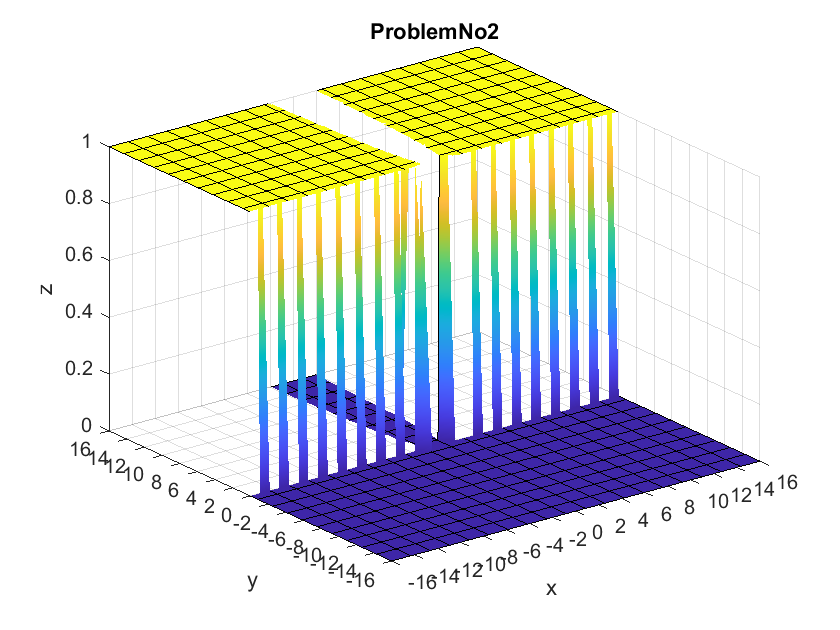

figure
fsurf(f(x,y),[-16 16 -16 16],'MeshDensity',20)
xlabel('x'); ylabel('y'); zlabel('z')
xticks(-16:2:16); yticks(-16:2:16)
title('ProblemNo2')


$$E\rho ώ\tau \eta \mu \alpha \:1.3$$



$$\Theta έ\tau o\nu \tau \alpha ς:$$



$$$$ x=r*\cos\theta ,y=r*\sin\theta$$$$



$$Έ\chi \omega :$$



$$$$ x^2=r^2*\cos^2\theta, y^2=r^2*\sin^2\theta$$$$



$$o\pi ό\tau \varepsilon :$$



$$$$x^2+y^2=r^2*\cos^2\theta+r^2*\sin^2\theta=r^2(\cos^2\theta+\sin^2\theta=r^2*1=r^2) $$$$



$$E\pi o\mu έ\nu \omega ς:$$



$$$$\lim_{r\to0} f(r,\theta)=\frac{\sin({r^2})}{r^2}=1\:\gamma \nu \omega \sigma \tau ό\:ό\rho \iota o\:\alpha \pi ό \:\tau o:\lim_{x\to0}\frac{\sin{x}}{x}$$  , $$


syms x y r
f(x,y)=sin(x^2+y^2)/(x^2+y^2)

$$f(x, y) = \frac{\sin\left(x^{2}+y^{2}\right)}{x^{2}+y^{2}}$$

%Με lim_(x,y)->(0,0)f(x,y)=1, θέτω
%r^2=x^2+y^2,lim_(x,y)->(0,0)(r^2)=0^2+0^2=0
r^2==x^2+y^2

$$ans = r^{2}=x^{2}+y^{2}$$

f_new(r)=sin(r^2)/r^2

$$f\_new(r) = \frac{\sin\left(r^{2}\right)}{r^{2}}$$

%θα έχω:f(r,θ)=sin(r^2)/r^2,επιβεβαίωση:
answer=limit(f_new,r,0)

$$answer = 1$$


$$E\rho ώ\tau \eta \mu \alpha \:1.4$$


syms x y 
z1=-3/7*x-2/7*y+1/7

$$z1 = \frac{1}{7}-\frac{2\,y}{7}-\frac{3\,x}{7}$$

z2=4-x^2-y^2

$$z2 = -x^{2}-y^{2}+4$$

c=solve(z1==z2,[x y])%Εύρεση σημείων τομής του επιπέδου-παραβολοειδούς/χρήση του στο διπλό ολοκλήρωμα για εύρεση όγκου

c = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


M=[c.x c.y]

$$M = \left(\begin{array}{cc} \frac{3}{14}-\frac{\sqrt{765}}{14} & 0\\ \frac{\sqrt{765}}{14}+\frac{3}{14} & 0 \end{array}\right)$$

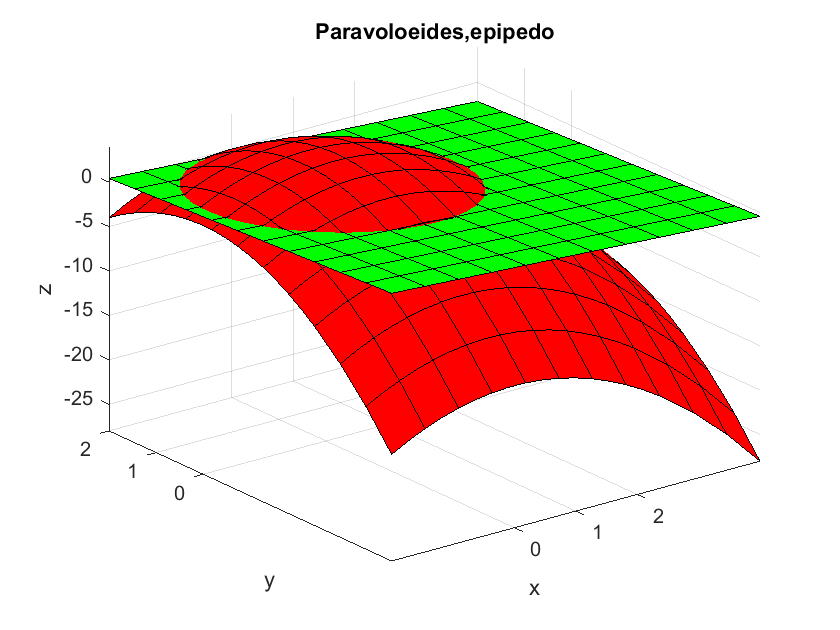

figure
fsurf(z1,[-2 4 -4  2],'g','MeshDensity',12); hold on%design of plane,paraboloid
fsurf(z2,[-2 4 -4  2],'r','MeshDensity',12); hold on
xlabel('x'); ylabel('y'); zlabel('z')
xticks(0:2); yticks(0:4);
title('Paravoloeides,epipedo')

I=int(int(z2-z1,x,3/14,sqrt(765)/14),y,-sqrt(765)/14,3/14)%volume calculation

$$I = \frac{81\,\sqrt{85}}{1372}+\frac{6885}{1372}$$

I_approximentation=double(I)

I_approximentation = 5.5625